# Add Paragraph to Content Placeholder

To add text to a content placeholder in a slide, use the `add` method of the `ContentPlaceholder` object. 

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation and add a `Title and Content` slide to the presentation.

ppt = Presentation("myContentPlaceholderAddPresentation.pptx");
open(ppt);
slide = add(ppt,"Title and Content");

Find the text box placeholder for the title and replace the content.

titlePlaceholderObj = find(slide,"Title");
replace(titlePlaceholderObj,"Fruits and Vegetables");

Find the content placeholder and replace the content with a paragraph.

contents = find(slide,"Content");
contentPlaceholderObj = contents(1);
replace(contentPlaceholderObj,{'Fruits' ["Apples" "Oranges"]});

Add another paragraph to the content placeholder.

add(contentPlaceholderObj,{"Vegetables" ["Beans" "Carrots"]});

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the slide in the generated presentation:

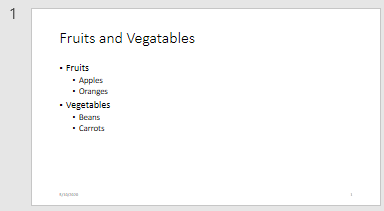

*Copyright 2020 The MathWorks, Inc.*